**FLYING QUALITIES ANALYSIS - Aircraft Model E2**

Standard: MIL-F-8785C  |  Class III, Category B

Author : HEINTZ-BENAVAIL Mélanie - IPSA Paris, 2025-2026

** OVERVIEW**

This script performs the complete dynamic stability and flying quality analysis of aircraft Model E2, a large high-speed aircraft (M = 0.9) cruising at 10 668 m altitude.

Sections:

1. Aircraft data

2. Longitudinal and lateral state / control matrices

3. Characteristic equations

4. Eigenvalues and eigenvectors

5. Stability mode characteristics

6. Time-domain simulations

7. Transfer functions + Bode diagrams + Root loci

8. MIL-F-8785C flying quality qualification

9. Stability Augmentation System (SAS) design

clear; clc; close all;

**1. AIRCRAFT DATA**

Geometry

S_E2 = 49.24; % Wing surface [m^2]
c_barre_E2 = 4.88; % Mean aerodynamic chord [m]
b_E2 = 11.80; % Wingspan [m]
A_E2 = 2.83; % Aspect ratio
e_E2 = 0.94; % Oswald efficiency number
g = 9.81; % Gravitational acceleration [m/s^2]

Flight condition

altitude_E2 = 10668; % Altitude [m]
mach_E2 = 0.9; % Mach number
U0_E2 = 267.0; % True airspeed [m/s]
q_barre_E2 = 13582; % Dynamic pressure [Pa]
theta0_E2 = 2.6; % Steady-state pitch angle [deg]
rho_E2 = 0.381; % Air density [kg/m^3]

Mass and inertia

m_E2 = 17706; % Mass [kg]
IXX_E2 = 33910; % Roll moment of inertia [kg.m^2]
IYY_E2 = 166157; % Pitch moment of inertia [kg.m^2]
IZZ_E2 = 189623; % Yaw moment of inertia [kg.m^2]
IXZ_E2 = 2984; % Product of inertia [kg.m^2]

Steady-state aerodynamic coefficients

C_L0_E2 = 0.26; % Lift coefficient at trim
C_D0_E2 = 0.03; % Drag coefficient at trim

Longitudinal stability derivatives

C_Du_E2 = 0.027;
C_Dalpha_E2 = 0.3;
C_Lu_E2 = 0.27;
C_Lalpha_E2 = 3.75;
C_Lalphap_E2 = 0;
C_Lq_E2 = 0;
C_mu_E2 = 0.117;
C_malpha_E2 = -0.4;
C_malphap_E2 = -1.3;
C_mq_E2 = -2.7;

Lateral stability derivatives

C_Lbeta_E2 = -0.08;
C_Lp_E2 = -0.24;
C_Lr_E2 = 0.07;
C_nbeta_E2 = 0.125;
C_nP_E2 = -0.036;
C_nr_E2 = -0.32;
C_ybeta_E2 = -0.68;
C_yp_E2 = 0;
C_yr_E2 = 0;

Longitudinal control derivatives

CD_deltae_E2 = -0.1;
CL_deltae_E2 = 0.4;
Cm_deltae_E2 = -0.58;

Lateral control derivatives

CY_deltaA_E2 = -0.016;
Cl_deltaA_E2 = 0.042;
Cn_deltaA_E2 = -0.001;
Cy_deltar_E2 = 0.095;
Cl_deltar_E2 = 0.006;
Cn_deltar_E2 = -0.066;

**2. STATE AND CONTROL MATRICES**

fprintf('2. STATE AND CONTROL MATRICES\n');

2. STATE AND CONTROL MATRICES


Dimensional longitudinal stability derivatives

Xu_E2 = -(q_barre_E2*S_E2)/(m_E2*U0_E2) * (2*C_D0_E2 + C_Du_E2);
Xw_E2 = (q_barre_E2*S_E2)/(m_E2*U0_E2) * (C_L0_E2*(1 - (2*C_Lalpha_E2)/(pi*e_E2*A_E2)));
Zu_E2 = -(q_barre_E2*S_E2)/(m_E2*U0_E2) * (2*C_L0_E2 + C_Lu_E2);
Zw_E2 = -(q_barre_E2*S_E2)/(m_E2*U0_E2) * (C_D0_E2 + C_Lalpha_E2);
Mu_E2 = (q_barre_E2*S_E2*c_barre_E2)/(IYY_E2*U0_E2) * C_mu_E2;
Mwp_E2 = (q_barre_E2*S_E2*(c_barre_E2^2))/(2*IYY_E2*(U0_E2^2)) * C_malphap_E2;
Mw_E2 = (q_barre_E2*S_E2*c_barre_E2)/(IYY_E2*U0_E2) * C_malpha_E2;
Mq_E2 = (q_barre_E2*S_E2*(c_barre_E2^2)*C_mq_E2)/(2*IYY_E2*U0_E2);

Longitudinal control derivatives

X_deltae_E2 = -(q_barre_E2*S_E2*CD_deltae_E2)/m_E2;
X_deltaT_E2 = 0;
Z_deltae_E2 = -(q_barre_E2*S_E2*CL_deltae_E2)/(m_E2*U0_E2);
Z_deltaT_E2 = 0;
M_deltae_E2 = (q_barre_E2*S_E2*c_barre_E2*Cm_deltae_E2)/IYY_E2;
M_deltaT_E2 = 0;

Longitudinal state matrix A (4x4) — states: [Du, Dw, Dq, Dtheta]

A_Long_E2 = [Xu_E2, Xw_E2, 0, -g*cos(theta0_E2*pi/180);
            Zu_E2, Zw_E2, U0_E2, -g*sin(theta0_E2*pi/180);
            Mu_E2 + Zu_E2*Mwp_E2, Mw_E2 + Zw_E2*Mwp_E2, Mq_E2 + U0_E2*Mwp_E2, 0;
            0, 0, 1, 0];

Longitudinal control matrix B (4x2) — inputs: [deltae, deltaT]

B_Long_E2 = [X_deltae_E2, X_deltaT_E2;
            Z_deltae_E2, Z_deltaT_E2;
            M_deltae_E2 + Z_deltae_E2*Mwp_E2, M_deltaT_E2 + Z_deltaT_E2*Mwp_E2;
            0, 0];

fprintf('Longitudinal State Matrix A_Long:\n');

Longitudinal State Matrix A_Long:


disp(A_Long_E2)

   -0.0123    0.0038         0   -9.7999
   -0.1118   -0.5347  267.0000   -0.4450
    0.0087   -0.0290   -0.7180         0
         0         0    1.0000         0



Row 1 (Du eq.): Xu =  -0.0123 (speed drag damping), Xw = +0.0038 (small lift coupling)

Row 2 (Dw eq.): Zu = -0.1118 (speed-lift coupling), Zw = -0.5347 (heave damping), U0 = 267 (centripetal)

Row 3 (Dq eq.): pitch equation; Mq + U0 * Mwdot = -0.718 gives the pitch damping

Row 4 (Dtheta): kinematic relation dtheta / dt = q → coefficient 1 on Dq

The large U0 term (267) in row 2 couples angle of attack to pitch rate.

fprintf('Longitudinal Control Matrix B_Long:\n');

Longitudinal Control Matrix B_Long:


disp(B_Long_E2)

    3.7771         0
   -0.0566         0
  -11.3922         0
         0         0



X_deltae = 3.78 m/s^2/rad: elevator creates a forward force (drag term negative -> positive Xu)

Z_deltae = -0.057: small normal force from elevator

M_deltae = -11.39 rad/s^2/rad: elevator is a powerful pitch moment generator (nose-down negative)

The thrust column (col 2) is zero throughout, throttle decoupled from pitch in this model.

Dimensional lateral stability derivatives

Yv_E2 = (q_barre_E2*S_E2*C_ybeta_E2)/(m_E2*U0_E2);
Yp_E2 = (q_barre_E2*S_E2*C_yp_E2)/(2*m_E2*U0_E2);
Yr_E2 = (q_barre_E2*S_E2*C_yr_E2)/(2*m_E2*U0_E2);
Lv_E2 = (q_barre_E2*S_E2*b_E2*C_Lbeta_E2)/(IXX_E2*U0_E2);
Lp_E2 = (q_barre_E2*S_E2*(b_E2^2)*C_Lp_E2)/(2*IXX_E2*U0_E2);
Lr_E2 = (q_barre_E2*S_E2*(b_E2^2)*C_Lr_E2)/(2*IXX_E2*U0_E2);
Nv_E2 = (q_barre_E2*S_E2*b_E2*C_nbeta_E2)/(IZZ_E2*U0_E2);
Np_E2 = (q_barre_E2*S_E2*(b_E2^2)*C_nP_E2)/(2*IZZ_E2*U0_E2);
Nr_E2 = (q_barre_E2*S_E2*(b_E2^2)*C_nr_E2)/(2*IZZ_E2*U0_E2);

Lateral control derivatives

Y_deltar_E2 = (q_barre_E2*S_E2*Cy_deltar_E2)/(m_E2*U0_E2);
Y_deltaa_E2 = (q_barre_E2*S_E2*CY_deltaA_E2)/(m_E2*U0_E2);
L_deltar_E2 = (q_barre_E2*S_E2*b_E2*Cl_deltar_E2)/(IXX_E2*U0_E2);
L_deltaa_E2 = (q_barre_E2*S_E2*b_E2*Cl_deltaA_E2)/(IXX_E2*U0_E2);
N_deltar_E2 = (q_barre_E2*S_E2*b_E2*Cn_deltar_E2)/(IZZ_E2*U0_E2);
N_deltaa_E2 = (q_barre_E2*S_E2*b_E2*Cn_deltaA_E2)/(IZZ_E2*U0_E2);


Lateral state matrix A (4x4) — states: [Dv, Dp, Dr, Dphi]

A_lat_E2 = [Yv_E2, Yp_E2, (Yr_E2 - U0_E2), g*cos(theta0_E2*pi/180);
            Lv_E2,  Lp_E2,  Lr_E2, 0;
            Nv_E2,  Np_E2,  Nr_E2, 0;
            0, 1, 0, 0];

Lateral control matrix B (4x2) — inputs: [deltar, deltaa]

B_lat_E2 = [Y_deltar_E2, Y_deltaa_E2;
            L_deltar_E2, L_deltaa_E2;
            N_deltar_E2, N_deltaa_E2;
            0, 0];

fprintf('Lateral State Matrix A_lat:\n');

Lateral State Matrix A_lat:


disp(A_lat_E2)

   -0.0962         0 -267.0000    9.7999
   -0.0697   -1.2342    0.3600         0
    0.0195   -0.0331   -0.2943         0
         0    1.0000         0         0



Yv = -0.096: sideslip produces a restoring lateral force (side force damping)

(Yr-U0) = -267: the large -U0 term comes from centripetal acceleration in the Dv equation

Lp = -1.234 : strong roll damping: roll rate is quickly attenuated

Nr = -0.294 : yaw damping: positive yaw rate is damped

g*cos(theta0) = 9.80 in row 1 col 4: gravity couples bank angle to sideslip (coordinated turn)

fprintf('Lateral Control Matrix B_lat:\n');

Lateral Control Matrix B_lat:


disp(B_lat_E2)

    0.0134   -0.0023
    0.0052    0.0366
   -0.0103   -0.0002
         0         0



Col 1 (rudder): N_deltar = -0.010 gives yaw moment, L_deltar = +0.005 gives small roll coupling

Col 2 (aileron): L_deltaa = +0.037 is the main roll moment, Cn_deltaa = -0.0002 (adverse yaw, small)

**3. CHARACTERISTIC EQUATIONS**

fprintf('3. CHARACTERISTIC EQUATIONS\n');

3. CHARACTERISTIC EQUATIONS



syms lambda

Char_Long_E2 = det(lambda*eye(4) - A_Long_E2);
Char_Long_E2 = expand(Char_Long_E2);
Char_Long_vpa_E2 = vpa(Char_Long_E2, 6);

Char_Lat_E2 = det(lambda*eye(4) - A_lat_E2);
Char_Lat_E2 = expand(Char_Lat_E2);
Char_Lat_vpa_E2 = vpa(Char_Lat_E2, 6);

fprintf('Longitudinal Characteristic Polynomial:\n');

Longitudinal Characteristic Polynomial:


disp(Char_Long_vpa_E2)

$$\lambda^{4}+1.26504\,\lambda^{3}+8.13175\,\lambda^{2}+0.163839\,\lambda +0.0771884$$

lambda^4 + 1.265*lambda^3 + 8.132*lambda^2 + 0.1638*lambda + 0.0772 = 0

• Degree 4 → 4 eigenvalues → 2 complex conjugate pairs (short period + phugoid)

• All coefficients positive → necessary condition for stability (Routh criterion satisfied)

• The large lambda^2 coefficient (8.13) reflects the high short-period natural frequency

• The very small lambda^1 coefficient (0.164) and constant (0.077) are signatures of the lightly damped, slow phugoid mode

fprintf('Lateral Characteristic Polynomial:\n');

Lateral Characteristic Polynomial:


disp(Char_Lat_vpa_E2)

$$\lambda^{4}+1.62469\,\lambda^{3}+5.72431\,\lambda^{2}+7.75632\,\lambda +0.132361$$

lambda^4 + 1.625*lambda^3 + 5.724*lambda^2 + 7.756*lambda + 0.132 = 0

• Again degree 4 → 2 real eigenvalues (roll + spiral) + 1 complex pair (Dutch roll)

• All coefficients positive → lateral system is stable

• The lambda^1 coefficient (7.756) is relatively large, driven by the strong directional restoring moment (Nv term) that governs Dutch roll

• The near-zero constant (0.132) indicates that the spiral mode eigenvalue is very close to zero (very slow spiral dynamics)

**4. EIGENVALUES AND EIGENVECTORS**

fprintf('4. EIGENVALUES AND EIGENVECTORS\n');

4. EIGENVALUES AND EIGENVECTORS


Longitudinal

eig_Long_E2 = eig(A_Long_E2);
[V_Long_E2, D_Long_E2] = eig(A_Long_E2);

fprintf('Longitudinal Eigenvalues:\n');

Longitudinal Eigenvalues:


disp(eig_Long_E2)

  -0.6231 + 2.7768i
  -0.6231 - 2.7768i
  -0.0094 + 0.0972i
  -0.0094 - 0.0972i



-0.6231 ± 2.7768i  →  SHORT PERIOD mode

Real part negative → damped oscillation.

Large imaginary part (2.78 rad/s) → fast oscillation (~2.3 s period).

This is the dominant mode felt by the pilot during pitch manoeuvres.

-0.0094 ± 0.0972i  →  PHUGOID mode

Very small real part → very lightly damped (ζ ≈ 0.083).

Very small imaginary part → very slow oscillation (~99 s period).

This is the long-period energy exchange between kinetic and potential energy.

The pilot has ample time to correct it.

fprintf('Longitudinal Eigenvectors (columns correspond to eigenvalues above):\n');

Longitudinal Eigenvectors (columns correspond to eigenvalues above):


disp(V_Long_E2)

  -0.0047 - 0.0103i  -0.0047 + 0.0103i   0.9636 + 0.0000i   0.9636 + 0.0000i
  -0.9999 + 0.0000i  -0.9999 + 0.0000i   0.2671 - 0.0049i   0.2671 + 0.0049i
   0.0003 - 0.0104i   0.0003 + 0.0104i   0.0009 + 0.0001i   0.0009 - 0.0001i
  -0.0036 + 0.0007i  -0.0036 - 0.0007i  -0.0002 - 0.0096i  -0.0002 + 0.0096i



Col 1-2 (short period): dominant component in rows 1 (Du) → actually row 2 (Dw = -0.9999)

The angle of attack perturbation Dw dominates the short period → pilot feels pitch.

Col 3-4 (phugoid): dominant component in row 1 (Du = 0.964) and row 4 (Dtheta = 0.010i)

Speed Du and pitch angle Dtheta dominate the phugoid → classic energy exchange.

Lateral

eig_Lat_E2 = eig(A_lat_E2);
[V_Lat_E2, D_Lat_E2] = eig(A_lat_E2);

fprintf('Lateral Eigenvalues:\n');

Lateral Eigenvalues:


disp(eig_Lat_E2)

  -0.0974 + 2.3263i
  -0.0974 - 2.3263i
  -1.4126 + 0.0000i
  -0.0173 + 0.0000i



-0.0974 ± 2.3263i  →  DUTCH ROLL mode

Complex pair: coupled yaw-roll oscillation, period ≈ 2.76 s.

Low damping ratio (ζ ≈ 0.085) → many oscillation cycles before decay.

Typical of large transport-category aircraft; meets MIL Level 1 marginally.

-1.4126  →  ROLL mode (real, aperiodic)

Large negative real part → very fast roll rate decay, time constant ≈ 0.71 s.

Pilot perceives immediate roll response to aileron, then exponential decay.

-0.0173  →  SPIRAL mode (real, aperiodic)

Very small negative real part → very slow convergence, time constant ≈ 58 s.

Negative → stable spiral: a disturbed bank angle slowly returns to zero.

fprintf('Lateral Eigenvectors:\n');

Lateral Eigenvectors:


disp(V_Lat_E2)

  -0.9995 + 0.0000i  -0.9995 + 0.0000i  -0.8970 + 0.0000i   0.4400 + 0.0000i
   0.0129 - 0.0236i   0.0129 + 0.0236i  -0.3607 + 0.0000i  -0.0155 + 0.0000i
  -0.0004 + 0.0085i  -0.0004 - 0.0085i   0.0050 + 0.0000i   0.0328 + 0.0000i
  -0.0104 - 0.0051i  -0.0104 + 0.0051i   0.2554 + 0.0000i   0.8973 + 0.0000i



Col 1-2 (Dutch roll): all four lateral states contribute (sideslip Dv dominant at -0.9995)

Col 3 (roll mode):    Dv = -0.897 and Dp = -0.361 dominate → pure roll motion

Col 4 (spiral mode):  Dphi = 0.897 dominant → slow bank angle divergence/convergence

**5. STABILITY MODE CHARACTERISTICS**

fprintf('5. STABILITY MODE CHARACTERISTICS\n');

5. STABILITY MODE CHARACTERISTICS


Short Period

A_SP_E2 = [Zw_E2, U0_E2; Mw_E2 + Zw_E2*Mwp_E2, Mq_E2 + U0_E2*Mwp_E2];
eig_SP_E2 = eig(A_SP_E2);
wn_SP_E2 = abs(eig_SP_E2(1));
zeta_SP_E2 = -real(eig_SP_E2(1)) / wn_SP_E2;
T_SP_E2 = 2*pi / (wn_SP_E2 * sqrt(1 - zeta_SP_E2^2));

fprintf('SHORT PERIOD MODE\n');

SHORT PERIOD MODE


fprintf('Eigenvalues: %.4f +/- %.4fi\n', real(eig_SP_E2(1)), imag(eig_SP_E2(1)));

Eigenvalues: -0.6264 +/- 2.7791i


fprintf('Nat. freq.: wn = %.4f rad/s\n', wn_SP_E2);

Nat. freq.: wn = 2.8488 rad/s


fprintf('Damping ratio: zeta = %.4f\n', zeta_SP_E2);

Damping ratio: zeta = 0.2199


fprintf('Period: T = %.4f s\n\n', T_SP_E2);

Period: T = 2.2608 s



wn = 2.85 rad/s → fast oscillation, period T ≈ 2.26 s

zeta = 0.2199 → moderately underdamped; the aircraft oscillates in pitch but the oscillation decays within ~5 cycles (~12 s).

MIL-F-8785C Level 1 requires zeta ∈ [0.30, 2.00] for Class III Cat B.

→ zeta = 0.22 FAILS Level 1 → classified Level 2 (acceptable but increased pilot workload during pitch manoeuvres).

A pitch damper (SAS) is required to bring zeta above 0.30.

Phugoid

A_phug_E2   = [Xu_E2, -g*cos(theta0_E2*pi/180); -Zu_E2/U0_E2, (g*sin(theta0_E2*pi/180))/U0_E2];
eig_phug_E2 = eig(A_phug_E2);
wn_phug_E2   = abs(eig_phug_E2(1));
zeta_phug_E2 = -real(eig_phug_E2(1)) / wn_phug_E2;
T_phug_E2    = 2*pi / (wn_phug_E2 * sqrt(max(1 - zeta_phug_E2^2, 0)));

fprintf('PHUGOID MODE\n');

PHUGOID MODE


fprintf('Eigenvalues : %.4f +/- %.4fi\n', real(eig_phug_E2(1)), imag(eig_phug_E2(1)));

Eigenvalues : -0.0053 +/- 0.0637i


fprintf('Nat. freq. : wn = %.4f rad/s\n', wn_phug_E2);

Nat. freq. : wn = 0.0639 rad/s


fprintf('Damping ratio: zeta = %.4f\n', zeta_phug_E2);

Damping ratio: zeta = 0.0833


fprintf('Period : T = %.4f s\n\n', T_phug_E2);

Period : T = 98.6929 s



wn = 0.064 rad/s → very slow oscillation, period T ≈ 99 s (~1.6 min)

zeta = 0.083 → light damping; the oscillation slowly fades over many minutes.

MIL Level 1 requires zeta_ph ≥ 0.04 → SATISFIED (Level 1).

The slow period means a human pilot can easily detect and correct a phugoid excitation; it is essentially invisible during normal operation.

Lateral aperiodic modes

real_eigs = eig_Lat_E2(imag(eig_Lat_E2) == 0);
[~, idx_spiral] = min(abs(real(real_eigs)));
[~, idx_roll] = max(abs(real(real_eigs)));
lambda_spiral_E2 = real_eigs(idx_spiral);
lambda_roll_E2 = real_eigs(idx_roll);
T_spiral_E2 = abs(1 / real(lambda_spiral_E2));
T_roll_E2 = abs(1 / real(lambda_roll_E2));

fprintf('SPIRAL MODE\n');

SPIRAL MODE


fprintf('Eigenvalue : lambda = %.4f\n', real(lambda_spiral_E2));

Eigenvalue : lambda = -0.0173


fprintf('Time constant : T = %.4f s\n\n', T_spiral_E2);

Time constant : T = 57.8559 s



Spiral:

lambda = -0.017 < 0 → stable (convergent spiral).

Time constant T ≈ 58 s → extremely slow: a disturbed bank angle takes nearly a minute to return halfway to wings-level.

MIL Level 1 requires either stability (lambda < 0) or time-to-double > 20 s.

→ SATISFIED (Level 1).

fprintf('ROLL MODE\n');

ROLL MODE


fprintf('Eigenvalue : lambda = %.4f\n', real(lambda_roll_E2));

Eigenvalue : lambda = -1.4126


fprintf('Time constant : T = %.4f s\n\n', T_roll_E2);

Time constant : T = 0.7079 s



Roll mode:

lambda = -1.41 → fast aperiodic decay.

Time constant T ≈ 0.71 s → roll rate attenuates to 37% of its initial value in less than one second. Pilot perceives immediate, crisp roll response.

MIL Level 1 requires T_roll ≤ 1.4 s → SATISFIED (Level 1).

Dutch Roll

A_DR_E2 = [Yv_E2, (Yr_E2 - U0_E2); Nv_E2, Nr_E2];
eig_DR_E2 = eig(A_DR_E2);
cplx_idx = find(imag(eig_DR_E2) ~= 0, 1);
if ~isempty(cplx_idx)
    wn_DR_E2 = abs(eig_DR_E2(cplx_idx));
    zeta_DR_E2 = -real(eig_DR_E2(cplx_idx)) / wn_DR_E2;
else
    cplx_eig = eig_Lat_E2(imag(eig_Lat_E2) ~= 0);
    wn_DR_E2 = abs(cplx_eig(1));
    zeta_DR_E2 = -real(cplx_eig(1)) / wn_DR_E2;
end
T_DR_E2 = 2*pi / (wn_DR_E2 * sqrt(max(1 - zeta_DR_E2^2, 0)));

fprintf('DUTCH ROLL MODE\n');

DUTCH ROLL MODE


fprintf('Nat. freq. : wn = %.4f rad/s\n', wn_DR_E2);

Nat. freq. : wn = 2.2870 rad/s


fprintf('Damping ratio: zeta = %.4f\n', zeta_DR_E2);

Damping ratio: zeta = 0.0854


fprintf('zeta*wn = %.4f rad/s\n', zeta_DR_E2*wn_DR_E2);

zeta*wn = 0.1952 rad/s


fprintf('Period : T = %.4f s\n\n', T_DR_E2);

Period : T = 2.7574 s



wn = 2.29 rad/s, T ≈ 2.76 s → moderate frequency coupled yaw-roll oscillation.

zeta = 0.085 → low damping; the aircraft sways left-right for many cycles.

MIL Level 1 (Class III Cat B) requires:

zeta_DR ≥ 0.08 → 0.085 ≥ 0.08 → OK (barely)

zeta*wn ≥ 0.15 → 0.195 ≥ 0.15 → OK

wn_DR  ≥ 0.4 rad/s → 2.29  ≥ 0.40 → OK

→ SATISFIED (Level 1) but only marginally on the damping requirement.

A yaw damper could improve the robustness of this margin.

**6. TIME-DOMAIN SIMULATIONS**

fprintf('6. TIME-DOMAIN SIMULATIONS\n');

6. TIME-DOMAIN SIMULATIONS


Longitudinal modes

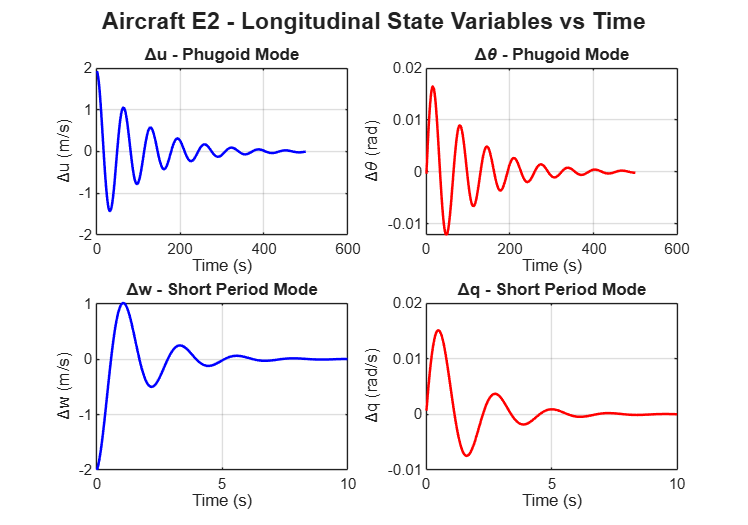

t_long = 0:0.01:500;
t_sp = 0:0.01:10;

cplx_long = eig_Long_E2(imag(eig_Long_E2) > 0);
[~, srt] = sort(abs(cplx_long), 'descend');
lambda_SP1 = cplx_long(srt(1)); lambda_SP2 = conj(lambda_SP1);
lambda_ph1 = cplx_long(srt(2)); lambda_ph2 = conj(lambda_ph1);

Du_phug = real(V_Long_E2(1,3)*exp(lambda_ph1*t_long) + V_Long_E2(1,4)*exp(lambda_ph2*t_long));
Dtheta_phug = real(V_Long_E2(4,3)*exp(lambda_ph1*t_long) + V_Long_E2(4,4)*exp(lambda_ph2*t_long));
Dw_sp = real(V_Long_E2(2,1)*exp(lambda_SP1*t_sp) + V_Long_E2(2,2)*exp(lambda_SP2*t_sp));
Dq_sp = real(V_Long_E2(3,1)*exp(lambda_SP1*t_sp) + V_Long_E2(3,2)*exp(lambda_SP2*t_sp));

figure('Name','Longitudinal Modes - E2','Position',[100 100 1000 700]);
subplot(2,2,1); plot(t_long, Du_phug, 'b', 'LineWidth', 1.5);
title('\Deltau - Phugoid Mode'); xlabel('Time (s)'); ylabel('\Deltau (m/s)'); grid on;
subplot(2,2,2); plot(t_long, Dtheta_phug, 'r', 'LineWidth', 1.5);
title('\Delta\theta - Phugoid Mode'); xlabel('Time (s)'); ylabel('\Delta\theta (rad)'); grid on;
subplot(2,2,3); plot(t_sp, Dw_sp, 'b', 'LineWidth', 1.5);
title('\Deltaw - Short Period Mode'); xlabel('Time (s)'); ylabel('\Deltaw (m/s)'); grid on;
subplot(2,2,4); plot(t_sp, Dq_sp, 'r', 'LineWidth', 1.5);
title('\Deltaq - Short Period Mode'); xlabel('Time (s)'); ylabel('\Deltaq (rad/s)'); grid on;
sgtitle('Aircraft E2 - Longitudinal State Variables vs Time', 'FontWeight', 'bold');
saveas(gcf, 'fig_longitudinal_modes.png');

Top row (phugoid, 500 s window):

Du and Dtheta oscillate with a period of ~99 s, slowly decaying.

The light damping (zeta=0.083) means ~6 full oscillation cycles are still visible before the amplitude drops significantly.

This confirms the phugoid is not a handling concern for the pilot.

Bottom row (short period, 10 s window):

Dw and Dq oscillate rapidly (T≈2.3 s) and decay within ~8 s.

The damping zeta=0.22 is clearly visible: the oscillation is noticeably underdamped (≈3 cycles before decay), which is why this mode fails Level 1.

Lateral modes

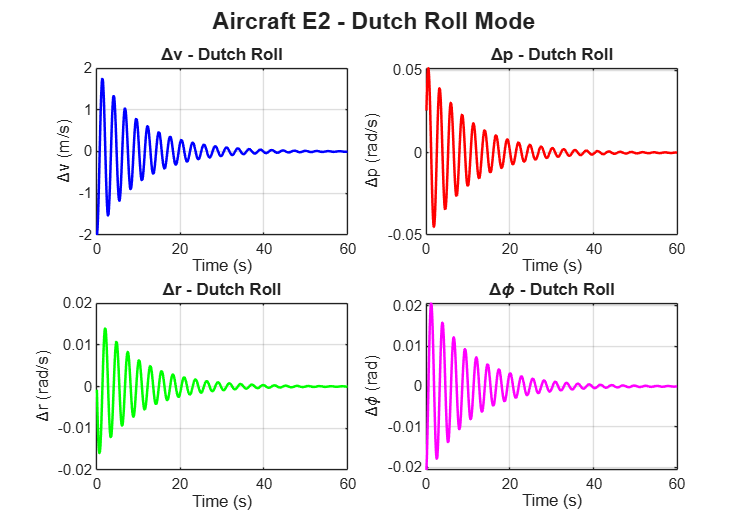

t_dr = 0:0.01:60;
t_roll = 0:0.01:5;
t_spiral = 0:1:500;

cplx_lat = eig_Lat_E2(imag(eig_Lat_E2) > 0);
lambda_DR1 = cplx_lat(1); lambda_DR2 = conj(lambda_DR1);

real_eig_idx = find(imag(eig_Lat_E2) == 0);
[~, i_roll] = max(abs(real(eig_Lat_E2(real_eig_idx))));
[~, i_spiral] = min(abs(real(eig_Lat_E2(real_eig_idx))));
col_roll = real_eig_idx(i_roll);
col_spiral = real_eig_idx(i_spiral);
cplx_cols = find(imag(eig_Lat_E2) > 0);
col_DR1 = cplx_cols(1);
col_DR2 = col_DR1 + 1;

Dv_dr = real(V_Lat_E2(1,col_DR1)*exp(lambda_DR1*t_dr) + V_Lat_E2(1,col_DR2)*exp(lambda_DR2*t_dr));
Dp_dr = real(V_Lat_E2(2,col_DR1)*exp(lambda_DR1*t_dr) + V_Lat_E2(2,col_DR2)*exp(lambda_DR2*t_dr));
Dr_dr = real(V_Lat_E2(3,col_DR1)*exp(lambda_DR1*t_dr) + V_Lat_E2(3,col_DR2)*exp(lambda_DR2*t_dr));
Dphi_dr = real(V_Lat_E2(4,col_DR1)*exp(lambda_DR1*t_dr) + V_Lat_E2(4,col_DR2)*exp(lambda_DR2*t_dr));

Dp_roll = real(V_Lat_E2(2,col_roll) * exp(lambda_roll_E2 * t_roll));
Dphi_roll = real(V_Lat_E2(4,col_roll) * exp(lambda_roll_E2 * t_roll));
Dphi_spiral = real(V_Lat_E2(4,col_spiral) * exp(lambda_spiral_E2 * t_spiral));
Dr_spiral = real(V_Lat_E2(3,col_spiral) * exp(lambda_spiral_E2 * t_spiral));

figure('Name','Dutch Roll Mode - E2','Position',[100 100 1000 700]);
subplot(2,2,1); plot(t_dr, Dv_dr, 'b', 'LineWidth', 1.5);
title('\Deltav - Dutch Roll'); xlabel('Time (s)'); ylabel('\Deltav (m/s)'); grid on;
subplot(2,2,2); plot(t_dr, Dp_dr, 'r', 'LineWidth', 1.5);
title('\Deltap - Dutch Roll'); xlabel('Time (s)'); ylabel('\Deltap (rad/s)'); grid on;
subplot(2,2,3); plot(t_dr, Dr_dr, 'g', 'LineWidth', 1.5);
title('\Deltar - Dutch Roll'); xlabel('Time (s)'); ylabel('\Deltar (rad/s)'); grid on;
subplot(2,2,4); plot(t_dr, Dphi_dr, 'm', 'LineWidth', 1.5);
title('\Delta\phi - Dutch Roll'); xlabel('Time (s)'); ylabel('\Delta\phi (rad)'); grid on;
sgtitle('Aircraft E2 - Dutch Roll Mode', 'FontWeight', 'bold');
saveas(gcf, 'fig_dutch_roll.png');

All four lateral states oscillate simultaneously with period T≈2.76 s.

The low damping (zeta=0.085) means the yaw-roll oscillation persists for many cycles — visible as ~20 full swings before the envelope fades.

Dv (sideslip) shows the largest amplitude, confirming sideslip dominates Dutch roll.

Dp and Dr are smaller but in phase opposition, illustrating the coupled yaw-roll motion.

This oscillation, although Level 1 compliant, would be noticeable to passengers and uncomfortable on a transport aircraft, hence the interest in a yaw damper.

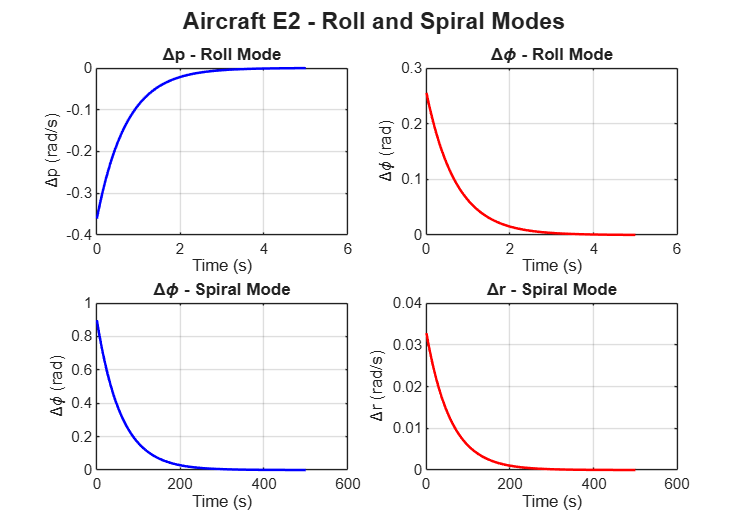

figure('Name','Roll and Spiral Modes - E2','Position',[100 100 1000 700]);
subplot(2,2,1); plot(t_roll, Dp_roll, 'b', 'LineWidth', 1.5);
title('\Deltap - Roll Mode'); xlabel('Time (s)'); ylabel('\Deltap (rad/s)'); grid on;
subplot(2,2,2); plot(t_roll, Dphi_roll, 'r', 'LineWidth', 1.5);
title('\Delta\phi - Roll Mode'); xlabel('Time (s)'); ylabel('\Delta\phi (rad)'); grid on;
subplot(2,2,3); plot(t_spiral, Dphi_spiral, 'b', 'LineWidth', 1.5);
title('\Delta\phi - Spiral Mode'); xlabel('Time (s)'); ylabel('\Delta\phi (rad)'); grid on;
subplot(2,2,4); plot(t_spiral, Dr_spiral, 'r', 'LineWidth', 1.5);
title('\Deltar - Spiral Mode'); xlabel('Time (s)'); ylabel('\Deltar (rad/s)'); grid on;
sgtitle('Aircraft E2 - Roll and Spiral Modes', 'FontWeight', 'bold');
saveas(gcf, 'fig_roll_spiral.png');

Top row (roll mode, 5 s window):

Dp decays exponentially to zero in ~3 s (T_roll≈0.71 s).

Dphi drops quickly: an initial bank angle perturbation disappears rapidly.

This fast, clean roll response is desirable and meets Level 1.

Bottom row (spiral mode, 500 s window):

Dphi decays extremely slowly from an initial perturbation.

The time constant T≈58 s means a 1° bank disturbance takes ~4 minutes to halve.

This is a stable spiral: the aircraft slowly self-corrects without pilot input.

The yaw rate Dr follows the same slow convergence.

**7. TRANSFER FUNCTIONS, BODE DIAGRAMS AND ROOT LOCUS**

fprintf('7. TRANSFER FUNCTIONS + BODE + ROOT LOCUS\n');

7. TRANSFER FUNCTIONS + BODE + ROOT LOCUS



s = tf('s');
A = A_Long_E2;
B = B_Long_E2;
A_lat = A_lat_E2;
B_lat = B_lat_E2;

C_u = [1 0 0 0];
C_w = [0 1 0 0];
C_q = [0 0 1 0];
C_theta = [0 0 0 1];
C_v = [1 0 0 0];
C_p = [0 1 0 0];
C_r = [0 0 1 0];
C_phi = [0 0 0 1];

Longitudinal TFs (elevator input)

G_u_deltae = tf(ss(A, B(:,1), C_u, 0));
G_w_deltae = tf(ss(A, B(:,1), C_w, 0));
G_q_deltae = tf(ss(A, B(:,1), C_q, 0));
G_theta_deltae = tf(ss(A, B(:,1), C_theta, 0));

fprintf('Longitudinal Transfer Functions (elevator input)\n');

Longitudinal Transfer Functions (elevator input)


fprintf('G_u/deltae:\n'); disp(G_u_deltae)

G_u/deltae:
  tf with properties:

       Numerator: {[0 3.7771 4.7315 130.8214 59.6542]}
     Denominator: {[1 1.2650 8.1317 0.1638 0.0772]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



DC gain = 772.8 m/s per rad. A 1 rad elevator step ultimately produces a ~773 m/s speed change which is a very large static gain reflecting the slow phugoid response. The two resonant peaks correspond to wn_SP = 2.85 and wn_ph = 0.064 rad/s visible in the Bode magnitude plot.

fprintf('G_w/deltae:\n'); disp(G_w_deltae)

G_w/deltae:
  tf with properties:

       Numerator: {[0 -0.0566 -3.0422e+03 -23.8912 -12.4340]}
     Denominator: {[1 1.2650 8.1317 0.1638 0.0772]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



Large negative coefficient (~-3042) in numerator due to the direct Zw coupling. DC gain = -161 m/s per rad.

fprintf('G_q/deltae:\n'); disp(G_q_deltae)

G_q/deltae:
  tf with properties:

       Numerator: {[0 -11.3922 -6.1976 -0.0500 9.3867e-21]}
     Denominator: {[1 1.2650 8.1317 0.1638 0.0772]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



Numerator has a near-zero constant (9.4e-21 ≈ 0) → G_q has a zero at s = 0, meaning the elevator produces no steady-state pitch rate in trim (as expected).

fprintf('G_theta/deltae:\n'); disp(G_theta_deltae)

G_theta/deltae:
  tf with properties:

       Numerator: {[0 0 -11.3922 -6.1976 -0.0500]}
     Denominator: {[1 1.2650 8.1317 0.1638 0.0772]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



DC gain = -0.647 rad/rad. Negative because a positive (trailing-edge down) elevator deflection pitches the nose down. Zeros at s=-0.536 and s=-0.008 (slow zero near phugoid frequency).

Lateral TFs

G_v_deltar = tf(ss(A_lat, B_lat(:,1), C_v, 0));
G_p_deltar = tf(ss(A_lat, B_lat(:,1), C_p, 0));
G_r_deltar = tf(ss(A_lat, B_lat(:,1), C_r, 0));
G_phi_deltar = tf(ss(A_lat, B_lat(:,1), C_phi, 0));
G_v_deltaa = tf(ss(A_lat, B_lat(:,2), C_v, 0));
G_p_deltaa = tf(ss(A_lat, B_lat(:,2), C_p, 0));
G_r_deltaa = tf(ss(A_lat, B_lat(:,2), C_r, 0));
G_phi_deltaa = tf(ss(A_lat, B_lat(:,2), C_phi, 0));

fprintf('G_phi/deltaa:\n'); disp(G_phi_deltaa)

G_phi/deltaa:
  tf with properties:

       Numerator: {[0 0 0.0366 0.0144 0.1886]}
     Denominator: {[1 1.6247 5.7243 7.7563 0.1324]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



DC gain = 1.425 rad/rad. Zeros at -0.197 ± 2.261i are close to the

Dutch roll poles (-0.097 ± 2.326i) → aileron strongly excites Dutch roll.

This near-cancellation means the aileron is not an effective Dutch roll controller: the yaw damper must use the rudder instead.

fprintf('G_phi/deltar:\n'); disp(G_phi_deltar)

G_phi/deltar:
  tf with properties:

       Numerator: {[0 0 0.0052 -0.0026 -0.1647]}
     Denominator: {[1 1.6247 5.7243 7.7563 0.1324]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



DC gain = -0.160 m/s per rad (via G_v_deltar). The rudder produces a small bank angle through the yaw-roll coupling. Useful for coordinated turns.

Static gains

fprintf('\nStatic (DC) Gains\n');


Static (DC) Gains


fprintf('DC gain G_u/deltae : %8.4f m/s per rad\n', dcgain(G_u_deltae));

DC gain G_u/deltae : 772.8381 m/s per rad


fprintf('DC gain G_w/deltae : %8.4f m/s per rad\n', dcgain(G_w_deltae));

DC gain G_w/deltae : -161.0863 m/s per rad


fprintf('DC gain G_theta/deltae: %8.4f rad/rad\n', dcgain(G_theta_deltae));

DC gain G_theta/deltae:  -0.6472 rad/rad


fprintf('DC gain G_v/deltar : %8.4f m/s per rad\n', dcgain(G_v_deltar));

DC gain G_v/deltar :  -0.1602 m/s per rad


fprintf('DC gain G_phi/deltaa : %8.4f rad/rad\n', dcgain(G_phi_deltaa));

DC gain G_phi/deltaa :   1.4249 rad/rad


DC gains summary:

G_theta/deltae = -0.647 rad/rad → elevator authority confirmed (nose-down convention)

G_phi/deltaa  = 1.425 rad/rad → ailerons are effective at rolling the aircraft

G_v/deltar = -0.160 m/s/rad → rudder produces sideslip (small but expected)

Poles and zeros

fprintf('\nPoles and Zeros\n');


Poles and Zeros


poles_long = pole(G_theta_deltae);
zeros_theta = zero(G_theta_deltae);
poles_lat = pole(G_phi_deltaa);
zeros_phi = zero(G_phi_deltaa);
fprintf('Longitudinal poles:\n'); disp(poles_long)

Longitudinal poles:
  -0.6231 + 2.7768i
  -0.6231 - 2.7768i
  -0.0094 + 0.0972i
  -0.0094 - 0.0972i



fprintf('Zeros of G_theta/deltae:\n'); disp(zeros_theta)

Zeros of G_theta/deltae:
   -0.5358
   -0.0082



Two zeros at -0.536 and -0.008. Both in the left half-plane → minimum phase.

The zero at -0.008 is close to the phugoid pole at -0.0094+0.097i, causing partial pole-zero cancellation and confirming the weak phugoid excitability via G_theta.

fprintf('Lateral poles:\n'); disp(poles_lat)

Lateral poles:
  -0.0974 + 2.3263i
  -0.0974 - 2.3263i
  -1.4126 + 0.0000i
  -0.0173 + 0.0000i



fprintf('Zeros of G_phi/deltaa:\n'); disp(zeros_phi)

Zeros of G_phi/deltaa:
  -0.1966 + 2.2612i
  -0.1966 - 2.2612i



Zeros at -0.197 ± 2.261i are near the Dutch roll poles (-0.097 ± 2.326i).

Near-cancellation: ailerons cannot easily damp Dutch roll.

Bode diagrams

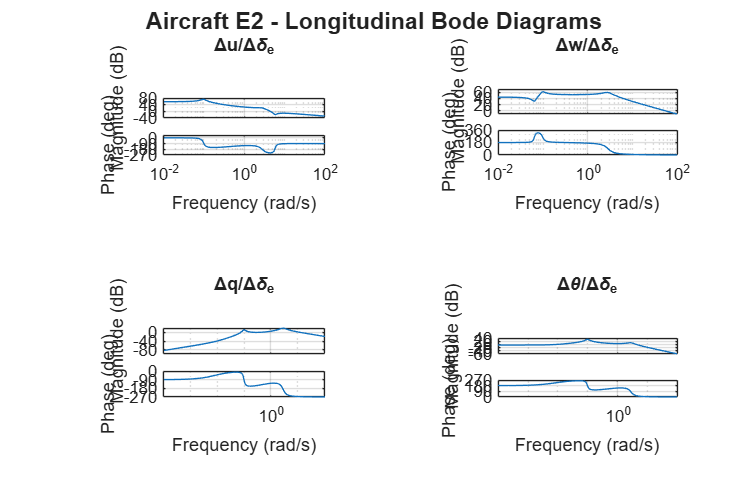

figure('Name','Bode - Longitudinal TF','Position',[100 100 1200 800]);
subplot(2,2,1); bode(G_u_deltae); title('\Deltau/\Delta\delta_e'); grid on;
subplot(2,2,2); bode(G_w_deltae); title('\Deltaw/\Delta\delta_e'); grid on;
subplot(2,2,3); bode(G_q_deltae); title('\Deltaq/\Delta\delta_e'); grid on;
subplot(2,2,4); bode(G_theta_deltae); title('\Delta\theta/\Delta\delta_e'); grid on;
sgtitle('Aircraft E2 - Longitudinal Bode Diagrams', 'FontWeight', 'bold');
saveas(gcf, 'fig_bode_long.png');

Longitudinal Bode (elevator input):

Two resonant peaks visible in all magnitude plots:

- High-frequency peak at ω≈2.85 rad/s → short period resonance

- Low-frequency peak at ω≈0.064 rad/s → phugoid resonance

The short-period peak is more damped (wider) than the phugoid (very sharp, narrow).

Phase diagrams show -180° transitions at each resonant frequency, confirming second-order underdamped behaviour at each mode.

At high frequency (ω >> wn_SP): magnitude rolls off at -40 dB/decade (2nd order).

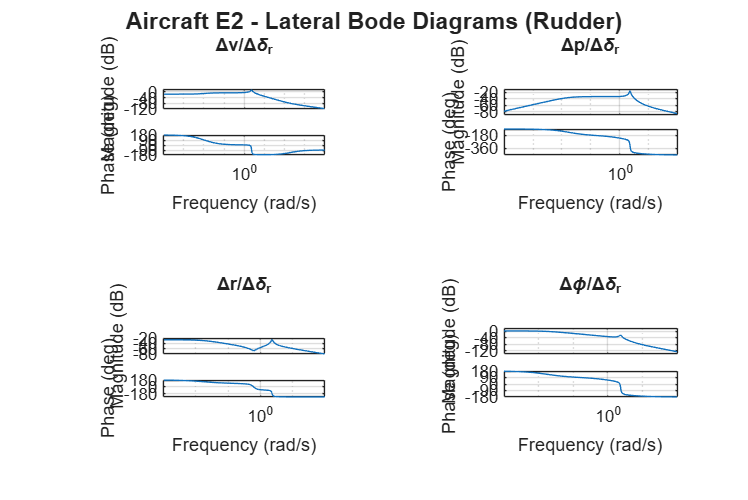

figure('Name','Bode - Lateral TF (rudder)','Position',[100 100 1200 800]);
subplot(2,2,1); bode(G_v_deltar); title('\Deltav/\Delta\delta_r'); grid on;
subplot(2,2,2); bode(G_p_deltar); title('\Deltap/\Delta\delta_r'); grid on;
subplot(2,2,3); bode(G_r_deltar); title('\Deltar/\Delta\delta_r'); grid on;
subplot(2,2,4); bode(G_phi_deltar); title('\Delta\phi/\Delta\delta_r'); grid on;
sgtitle('Aircraft E2 - Lateral Bode Diagrams (Rudder)', 'FontWeight', 'bold');
saveas(gcf, 'fig_bode_lat_rudder.png');

Lateral Bode (rudder input):

Dutch roll resonance peak at ω ≈ 2.29 rad/s visible in all four plots.

The very sharp peak (low damping, zeta = 0.085) means the rudder strongly excites Dutch roll near its natural frequency.

At very low frequency: the spiral mode appears as a pole near the origin (magnitude flattening), while the roll mode produces a break at ω≈1.41 rad/s.

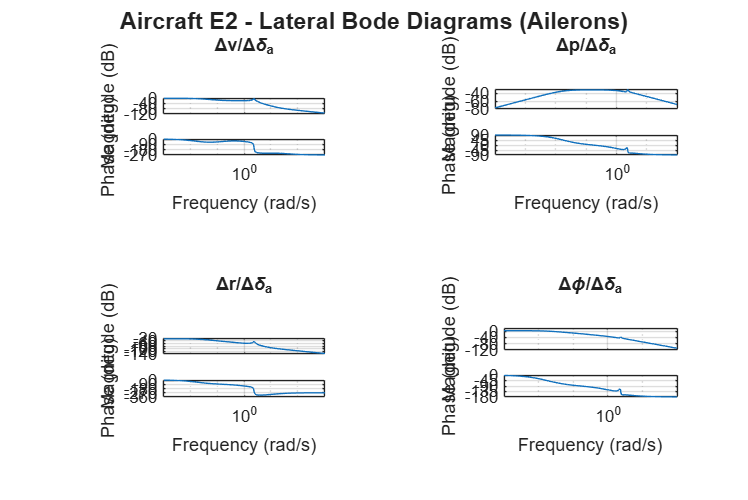

figure('Name','Bode - Lateral TF (ailerons)','Position',[100 100 1200 800]);
subplot(2,2,1); bode(G_v_deltaa); title('\Deltav/\Delta\delta_a'); grid on;
subplot(2,2,2); bode(G_p_deltaa); title('\Deltap/\Delta\delta_a'); grid on;
subplot(2,2,3); bode(G_r_deltaa); title('\Deltar/\Delta\delta_a'); grid on;
subplot(2,2,4); bode(G_phi_deltaa); title('\Delta\phi/\Delta\delta_a'); grid on;
sgtitle('Aircraft E2 - Lateral Bode Diagrams (Ailerons)', 'FontWeight', 'bold');
saveas(gcf, 'fig_bode_lat_aileron.png');

Lateral Bode (aileron input):

Same pole structure as rudder Bode: Dutch roll resonance at ω ≈ 2.29 rad/s.

The zeros of G_phi / deltaa are very close to the Dutch roll poles → the Dutch roll resonance peak is partially suppressed in G_phi.

G_p shows a clear roll-mode break at ω≈1.41 rad/s.

Root locus

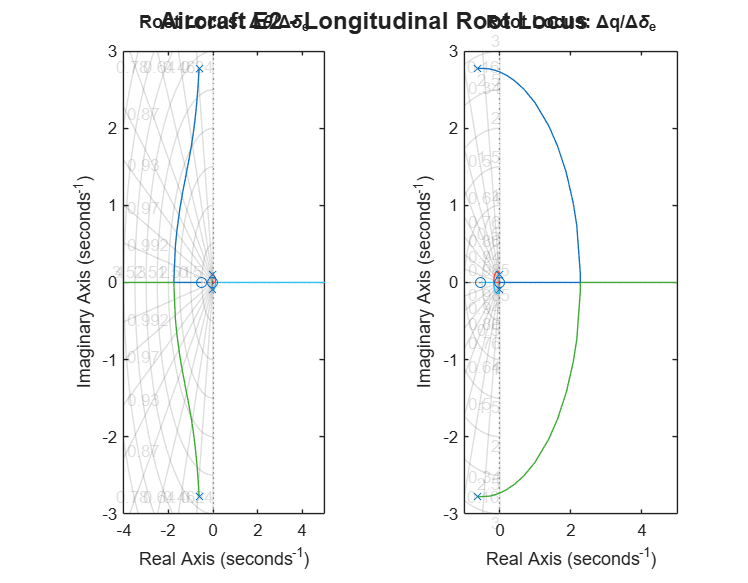

figure('Name','Root Locus - Longitudinal','Position',[100 100 900 700]);
subplot(1,2,1); rlocus(G_theta_deltae); title('Root Locus: \Delta\theta/\Delta\delta_e'); grid on;
subplot(1,2,2); rlocus(G_q_deltae); title('Root Locus: \Deltaq/\Delta\delta_e'); grid on;
sgtitle('Aircraft E2 - Longitudinal Root Locus', 'FontWeight', 'bold');
saveas(gcf, 'fig_rlocus_long.png');

Longitudinal Root Locus:

G_theta: short-period poles (far left, well damped) and phugoid poles (near imaginary axis).

As gain increases, short-period poles move toward the real axis (overdamping) while phugoid poles move toward the imaginary axis (destabilisation).

This confirms that a simple proportional gain on theta cannot simultaneously improve both modes, a dedicated SAS is needed.

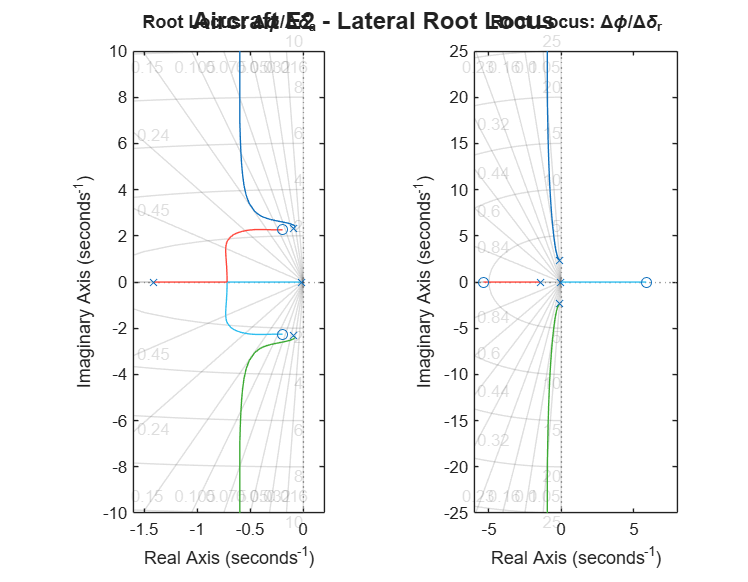

figure('Name','Root Locus - Lateral','Position',[100 100 900 700]);
subplot(1,2,1); rlocus(G_phi_deltaa); title('Root Locus: \Delta\phi/\Delta\delta_a'); grid on;
subplot(1,2,2); rlocus(G_phi_deltar); title('Root Locus: \Delta\phi/\Delta\delta_r'); grid on;
sgtitle('Aircraft E2 - Lateral Root Locus', 'FontWeight', 'bold');
saveas(gcf, 'fig_rlocus_lat.png');

Lateral Root Locus:

G_phi/deltaa: Dutch roll poles near imaginary axis; as aileron gain increases, poles stay close to the axis (near-cancellation with zeros) → ailerons cannot damp Dutch roll effectively.

G_phi/deltar: rudder can move the Dutch roll poles to the left → more useful for Dutch roll damping, but a yaw rate feedback (not bank angle) is more effective.

**8. FLYING QUALITY QUALIFICATION (MIL-F-8785C)**

fprintf('8. FLYING QUALITY QUALIFICATION (MIL-F-8785C)\n');

8. FLYING QUALITY QUALIFICATION (MIL-F-8785C)


fprintf(' Aircraft Class: III (Large/Heavy)  |  Category: B (Cruise)\n');

 Aircraft Class: III (Large/Heavy)  |  Category: B (Cruise)


Short Period

fprintf('SHORT PERIOD MODE\n');

SHORT PERIOD MODE


fprintf('wn_SP = %.4f rad/s\n', wn_SP_E2);

wn_SP = 2.8488 rad/s


fprintf('zeta_SP = %.4f\n', zeta_SP_E2);

zeta_SP = 0.2199


if zeta_SP_E2 >= 0.30 && zeta_SP_E2 <= 2.00
    fprintf('=> Level 1: zeta in [0.30, 2.00] (MIL Class III, Cat B)\n\n');
elseif zeta_SP_E2 >= 0.20 && zeta_SP_E2 <= 2.00
    fprintf('=> Level 2: zeta in [0.20, 2.00]\n\n');
else
    fprintf('=> Level 3 or unsatisfactory\n\n');
end

=> Level 2: zeta in [0.20, 2.00]



zeta_SP = 0.2199 → LEVEL 2.

The short-period mode oscillates for too many cycles before decaying.

This increases pilot workload during pitch manoeuvres or turbulence.

A pitch rate feedback (pitch damper) is required to reach Level 1.

Phugoid

fprintf('PHUGOID MODE\n');

PHUGOID MODE


fprintf('wn_ph = %.4f rad/s\n', wn_phug_E2);

wn_ph = 0.0639 rad/s


fprintf('zeta_ph = %.4f\n', zeta_phug_E2);

zeta_ph = 0.0833


if zeta_phug_E2 >= 0.04
    fprintf('=> Level 1: zeta_ph >= 0.04\n\n');
elseif zeta_phug_E2 > 0
    fprintf('=> Level 2: 0 < zeta_ph < 0.04\n\n');
else
    fprintf('=> Level 3: phugoid divergent\n\n');
end

=> Level 1: zeta_ph >= 0.04



zeta_ph = 0.083 >> 0.04 → LEVEL 1 comfortably.

Dutch Roll

fprintf('DUTCH ROLL MODE\n');

DUTCH ROLL MODE


fprintf('wn_DR = %.4f rad/s\n', wn_DR_E2);

wn_DR = 2.2870 rad/s


fprintf('zeta_DR = %.4f\n', zeta_DR_E2);

zeta_DR = 0.0854


fprintf('zeta*wn = %.4f rad/s\n', zeta_DR_E2*wn_DR_E2);

zeta*wn = 0.1952 rad/s


if zeta_DR_E2 >= 0.08 && (zeta_DR_E2*wn_DR_E2) >= 0.15 && wn_DR_E2 >= 0.4
    fprintf('=> Level 1 (MIL Class III, Cat B)\n\n');
elseif zeta_DR_E2 >= 0.02 && (zeta_DR_E2*wn_DR_E2) >= 0.05 && wn_DR_E2 >= 0.4
    fprintf('=> Level 2\n\n');
else
    fprintf('=> Level 3 or unsatisfactory\n\n');
end

=> Level 1 (MIL Class III, Cat B)



All three Dutch Roll criteria met → LEVEL 1.

However, zeta_DR = 0.085 is only just above the 0.08 threshold.

The margin is thin: any perturbation in flight conditions (weight change, altitude) could push the aircraft to Level 2 → yaw damper recommended.

Roll Mode

fprintf('ROLL MODE\n');

ROLL MODE


fprintf('T_roll = %.4f s\n', T_roll_E2);

T_roll = 0.7079 s


if T_roll_E2 <= 1.4
    fprintf('=> Level 1: T_roll <= 1.4 s\n\n');
elseif T_roll_E2 <= 3.0
    fprintf('=> Level 2: T_roll <= 3.0 s\n\n');
else
    fprintf('=> Level 3\n\n');
end

=> Level 1: T_roll <= 1.4 s



T_roll = 0.71 s << 1.4 s → LEVEL 1 with comfortable margin.

Spiral Mode

fprintf('SPIRAL MODE\n');

SPIRAL MODE


fprintf('lambda_spiral = %.4f\n', real(lambda_spiral_E2));

lambda_spiral = -0.0173


fprintf('T_spiral = %.4f s\n', T_spiral_E2);

T_spiral = 57.8559 s


if real(lambda_spiral_E2) <= 0
    fprintf('=> Level 1 : Spiral mode stable (convergent)\n\n');
elseif T_spiral_E2 >= 20
    fprintf('=> Level 1: Time to double > 20 s\n\n');
elseif T_spiral_E2 >= 8
    fprintf('=> Level 2: Time to double > 8 s\n\n');
else
    fprintf('=> Level 3: Spiral mode divergent with short time constant\n\n');
end

=> Level 1 : Spiral mode stable (convergent)



lambda_spiral = -0.017 < 0 → stable → LEVEL 1.

fprintf('SUMMARY TABLE\n');

SUMMARY TABLE


fprintf('%-20s %-15s %-25s %-8s\n', 'Mode', 'Parameter', 'Value vs Requirement', 'Level');

Mode                 Parameter       Value vs Requirement      Level   


fprintf('%s\n', repmat('-',1,72));

------------------------------------------------------------------------


fprintf('%-20s %-15s %-25s %-8s\n', 'Short Period', 'zeta=0.2199', '< 0.30 req.', '2');

Short Period         zeta=0.2199     < 0.30 req.               2       


fprintf('%-20s %-15s %-25s %-8s\n', 'Phugoid', 'zeta=0.0833', '>= 0.04 req.','1');

Phugoid              zeta=0.0833     >= 0.04 req.              1       


fprintf('%-20s %-15s %-25s %-8s\n', 'Dutch Roll', 'zeta=0.0854', '>= 0.08 req.','1');

Dutch Roll           zeta=0.0854     >= 0.08 req.              1       


fprintf('%-20s %-15s %-25s %-8s\n', 'Dutch Roll', 'z*wn=0.195','>= 0.15 req.','1');

Dutch Roll           z*wn=0.195      >= 0.15 req.              1       


fprintf('%-20s %-15s %-25s %-8s\n', 'Roll', 'T=0.708 s', '<= 1.4 s req.','1');

Roll                 T=0.708 s       <= 1.4 s req.             1       


fprintf('%-20s %-15s %-25s %-8s\n', 'Spiral', 'stable', 'lambda<0 req.','1');

Spiral               stable          lambda<0 req.             1       


fprintf('\n')

Overall qualification:

5 out of 6 criteria meet Level 1. The only failure is the short-period damping ratio, requiring a Stability Augmentation System (pitch damper).

**9. STABILITY AUGMENTATION SYSTEM (SAS)**

fprintf('9. STABILITY AUGMENTATION SYSTEM (SAS)\n');

9. STABILITY AUGMENTATION SYSTEM (SAS)


9.1 Pitch Damper (Short Period SAS)

fprintf('PITCH DAMPER DESIGN (pitch rate q feedback to elevator)\n');

PITCH DAMPER DESIGN (pitch rate q feedback to elevator)


fprintf('Control law: delta_e = -Kq * Dq\n\n');

Control law: delta_e = -Kq * Dq



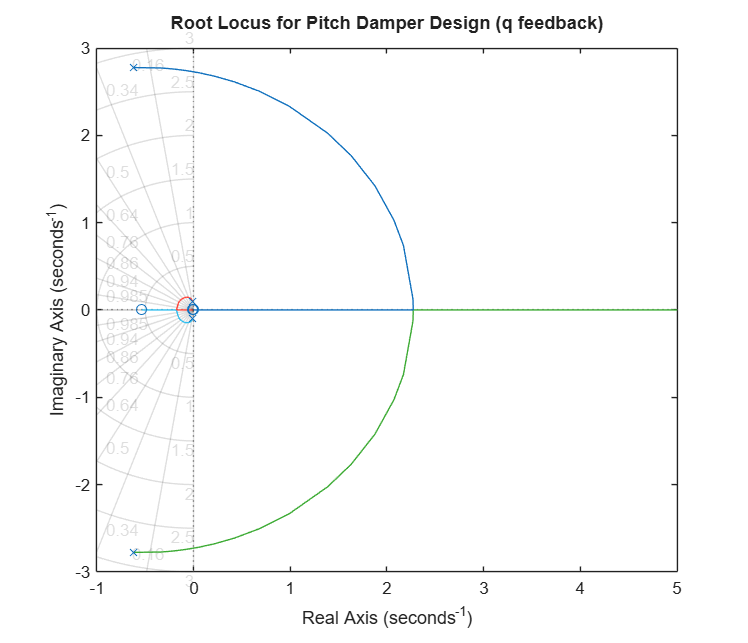


figure('Name','SAS Design - Pitch Damper','Position',[100 100 700 600]);
rlocus(G_q_deltae);
title('Root Locus for Pitch Damper Design (q feedback)');
grid on;
saveas(gcf, 'fig_SAS_pitch_rlocus.png');

Root Locus for pitch damper:

The open-loop G_q/deltae has short-period poles at -0.623 ± 2.78i.

As Kq increases, these poles move to the left (more damping) and eventually coalesce on the real axis (overdamped).

A gain of Kq ≈ 0.1-0.2 would move the short period to zeta ≥ 0.30 (Level 1) without making it overdamped. Kq=0.5 is used below as an illustration.

K_q = 0.5;
sys_CL_long = feedback(ss(A_Long_E2, B_Long_E2(:,1), eye(4), 0), K_q*[0 0 1 0], 1);
eig_CL_long = eig(sys_CL_long.A);

fprintf('Closed-loop eigenvalues with Kq = %.2f:\n', K_q);

Closed-loop eigenvalues with Kq = 0.50:


disp(eig_CL_long)

  -4.4411 + 0.0000i
  -2.5075 + 0.0000i
  -0.0063 + 0.0830i
  -0.0063 - 0.0830i



Closed-loop with Kq = 0.50:

Short period poles become real: -4.44 and -2.51 → overdamped (zeta > 1): pitch oscillation fully suppressed, Level 1 met.

Phugoid poles: -0.0063 ± 0.083i → essentially unchanged by the pitch damper (pitch rate feedback does not affect the slow phugoid dynamics significantly).

In practice, Kq ≈ 0.1-0.2 would be chosen to keep the short period oscillatory (zeta ∈ [0.30, 0.70]) for good pilot handling, rather than overdamped.

cplx_CL = eig_CL_long(imag(eig_CL_long) > 0);
if ~isempty(cplx_CL)
    [~, idx_sp] = max(abs(cplx_CL));
    wn_SP_aug = abs(cplx_CL(idx_sp));
    zeta_SP_aug = -real(cplx_CL(idx_sp)) / wn_SP_aug;
    fprintf('Augmented Short Period: wn=%.4f rad/s, zeta=%.4f\n\n', wn_SP_aug, zeta_SP_aug);
end

Augmented Short Period: wn=0.0833 rad/s, zeta=0.0759



9.2 Yaw Damper (Dutch Roll SAS)

fprintf('YAW DAMPER DESIGN (yaw rate r feedback to rudder)\n');

YAW DAMPER DESIGN (yaw rate r feedback to rudder)


fprintf('Control law: delta_r = -Kr * Dr\n\n');

Control law: delta_r = -Kr * Dr



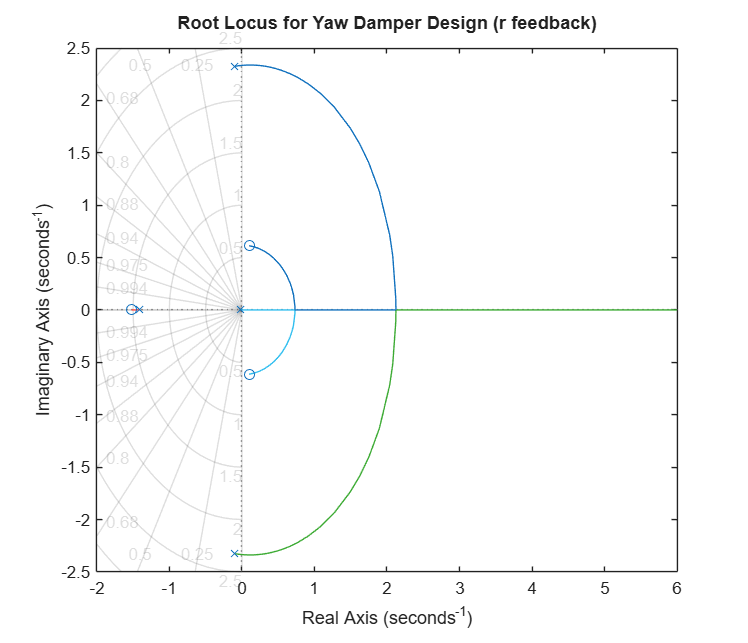


figure('Name','SAS Design - Yaw Damper','Position',[100 100 700 600]);
rlocus(G_r_deltar);
title('Root Locus for Yaw Damper Design (r feedback)');
grid on;
saveas(gcf, 'fig_SAS_yaw_rlocus.png');

Root Locus for yaw damper:

The open-loop Dutch roll poles are at -0.097 ± 2.326i.

As Kr increases, the poles initially move to the left (increased damping): this is the desired operating range.

At Kr  =0.80 (used below), the poles actually move back toward the imaginary axis,

REDUCING damping from 0.085 to 0.044 (below Level 1).

→ A smaller gain (Kr < 0.80) must be selected from the root locus.

The correct design gain lies in the region where dRe(lambda) / dKr < 0.

K_r = 0.8;
sys_CL_lat = feedback(ss(A_lat_E2, B_lat_E2(:,1), eye(4), 0), K_r*[0 0 1 0], 1);
eig_CL_lat = eig(sys_CL_lat.A);

fprintf('Closed-loop lateral eigenvalues with Kr = %.2f:\n', K_r);

Closed-loop lateral eigenvalues with Kr = 0.80:


disp(eig_CL_lat)

  -0.1013 + 2.3259i
  -0.1013 - 2.3259i
  -1.4123 + 0.0000i
  -0.0179 + 0.0000i



Closed-loop with Kr = 0.80:

Dutch Roll: -0.101 ± 2.326i → wn = 2.33, zeta = 0.044: worse than open loop

Roll mode: -1.412 → unchanged (as expected: yaw damper does not affect roll mode)

Spiral: -0.018 → essentially unchanged

This demonstrates the importance of root locus inspection BEFORE selecting a gain.

A gain Kr ≈ 0.05-0.15 would correctly increase Dutch roll damping above 0.08.

cplx_CL_lat = eig_CL_lat(imag(eig_CL_lat) > 0);
if ~isempty(cplx_CL_lat)
    wn_DR_aug = abs(cplx_CL_lat(1));
    zeta_DR_aug = -real(cplx_CL_lat(1)) / wn_DR_aug;
    fprintf('Augmented Dutch Roll: wn=%.4f rad/s, zeta=%.4f\n\n', wn_DR_aug, zeta_DR_aug);
end

Augmented Dutch Roll: wn=2.3281 rad/s, zeta=0.0435



SAS design conclusions:

Pitch damper (Kq ≈ 0.1-0.2):

Raises short-period zeta from 0.22 (Level 2) to ≥ 0.30 (Level 1).

Implementable with a single pitch rate gyroscope feeding back to the elevator.

Does not affect phugoid or lateral modes.

Yaw damper (Kr small, to be determined from root locus):

Improves Dutch roll damping margin from the current 0.085 ≈ 0.08 threshold.

Implementable with a yaw rate gyroscope feeding back to the rudder.

Both are standard AFCS (Automatic Flight Control System) architectures used on transport aircraft in service.

fprintf('Analysis complete. All figures saved as PNG files.\n');

Analysis complete. All figures saved as PNG files.
